load('raw_data/increasing force 2.mat')
x = out_mat;

% place holder for x_filtered
x_filtered = zeros(size(x));

% filtered the raw waveform by 
% a [200 500] bandpass filter
size(x, 1)

ans = 64

for i = 1:size(x, 1)
    x_filtered(i,:) = bandpass(x(i,:),[200 500],4e3);
end

% cut off head and tail with artifacts
x_ready = x_filtered(:, 2000:length(x_filtered)-2000);
save('increasing_force_2_ready.mat', 'x_ready')

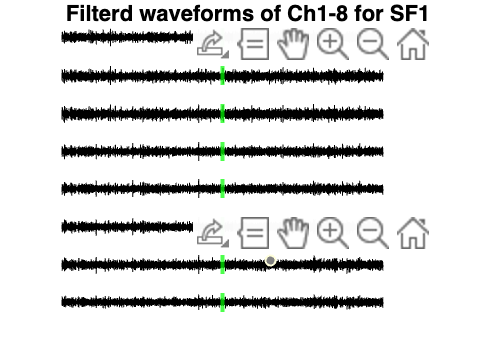

% plot waveforms of ch1-8, eyeballing the latency
subplot(8,1,1)
plot(x_ready(1,:), 'black')
ylabel('Ch1')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
title('Filterd waveforms of Ch1-8 for SF1')
subplot(8,1,2)
plot(x_ready(2,:), 'black')
ylabel('Ch2')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
subplot(8,1,3)
plot(x_ready(3,:), 'black')
ylabel('Ch3')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
subplot(8,1,4)
plot(x_ready(4,:), 'black')
ylabel('Ch4')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
subplot(8,1,5)
plot(x_ready(5,:), 'black')
ylabel('Ch5')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
subplot(8,1,6)
plot(x_ready(6,:), 'black')
ylabel('Ch6')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
subplot(8,1,7)
plot(x_ready(7,:), 'black')
ylabel('Ch7')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)
subplot(8,1,8)
plot(x_ready(8,:), 'black')
ylabel('Ch8')
axis off
xline(length(x_ready) / 2, 'green','LineWidth',2.0)

% x_ready(1,:)
% x_ready(2,:)
% close all;
% plot(x_ready(1,2000:4000))
% x__ = x_ready
% x_mean = mean(x__)

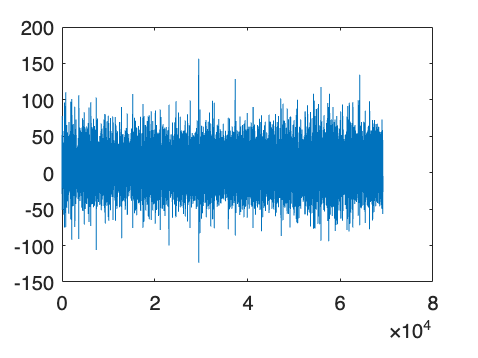

% we don't observe any latency
% both quantitatively and qualitatively
% so we simply average all 64 waveform
x_mean = mean(x_ready);
close all;
plot(x_mean)

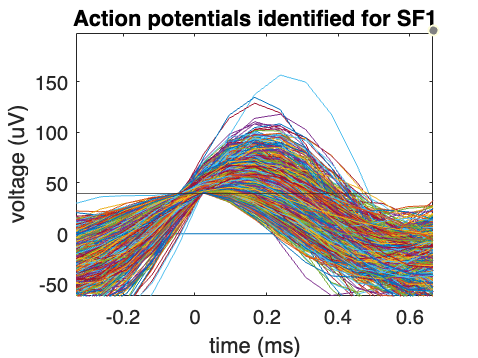

% thresholding the waveform to find spikes
close all;
x_threshold = x_mean > 40;
idx = strfind(x_threshold,[0 1])+1;
waves = zeros(length(idx), 15);
for i = 1:length(idx)
    if idx(i)-5 < 1
        continue
    end
    waves(i,:) = x_mean(idx(i)-5:idx(i)+9);
end
clear i;

close all;
t = linspace(-1/3,2/3,15);
for i = 1:length(idx)
    plot(t, waves(i,:));
    hold on
end
clear i;

yline(40)
xlim([-1/3 2/3])
xlabel('time (ms)')
ylabel('voltage (uV)')
title('Action potentials identified for SF1')

% PCA
covariance = cov(waves);
[U, Lambda] = eig(covariance);
lambdas = diag(Lambda);

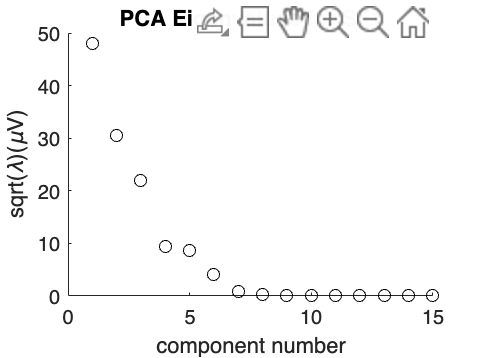

% find the elbow
close all;
component_num = 0:14;
component_num = 15 - component_num;
scatter(component_num, sqrt(lambdas), 'o', 'black')
xlabel('component number')
ylabel('sqrt(\lambda)(\muV)')
title('PCA Eigenvalues for SF1')

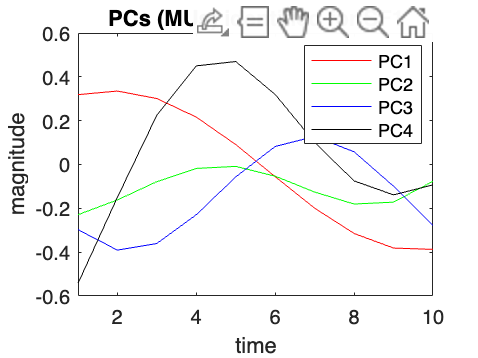

% plot PCs found
[m_values, m_indices] = maxk(lambdas, 4);
close all;
plot(U(:, m_indices(1)), 'red')
hold on
plot(U(:, m_indices(2)), 'green')
hold on
plot(U(:, m_indices(3)), 'blue')
hold on
plot(U(:, m_indices(4)), 'black')
xlim([1 10]);
xlabel('time')
ylabel('magnitude')
legend('PC1', 'PC2', 'PC3', 'PC4')
title('PCs (MUs) identified for SF1')

% assign the spikes to responsible MU
mu = mean(waves, 1);
pc_scores = U(:, m_indices(1:4))' * (waves - mu)';
[max_score, max_idx] = max(pc_scores);
mu1_spikes = idx(max_idx == 1);
mu2_spikes = idx(max_idx == 2);
mu3_spikes = idx(max_idx == 3);
mu4_spikes = idx(max_idx == 4);


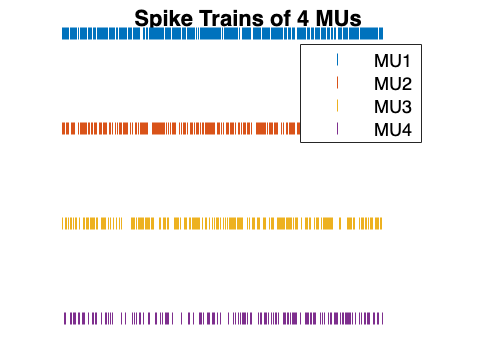

close all;
mu1_spike_train = 4 * ones(1, length(mu1_spikes));
scatter(mu1_spikes, mu1_spike_train, '|');
hold on
mu2_spike_train = 3 * ones(1, length(mu2_spikes));
scatter(mu2_spikes, mu2_spike_train, '|');
hold on
mu3_spike_train = 2 * ones(1, length(mu3_spikes));
scatter(mu3_spikes, mu3_spike_train, '|');
hold on
mu4_spike_train = 1 * ones(1, length(mu4_spikes));
scatter(mu4_spikes, mu4_spike_train, '|');
axis off
title('Spike Trains of 4 MUs')
legend('MU1', 'MU2', 'MU3', 'MU4')

% caculate the ISI
mu1_isi = diff(mu1_spikes);
mu2_isi = diff(mu2_spikes);
mu3_isi = diff(mu3_spikes);
mu4_isi = diff(mu4_spikes);

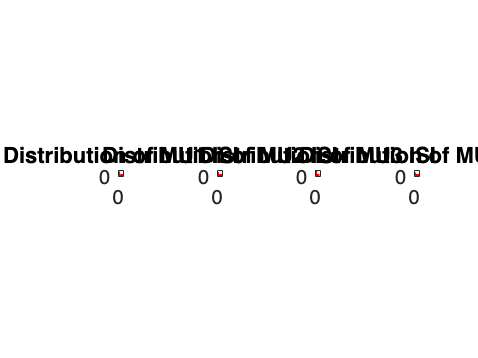

% plot ISI distributions of MUs
close all;
subplot(1, 4, 1)
histfit(mu1_isi, 50, 'exponential');
xlabel('Inte Spike Interval')
ylabel('Counts')
title('Distribution of MU1 ISI')
axis square
subplot(1, 4, 2)
histfit(mu2_isi, 50, 'exponential');
xlabel('Inte Spike Interval')
ylabel('Counts')
title('Distribution of MU2 ISI')
axis square
subplot(1, 4, 3)
histfit(mu3_isi, 50, 'exponential');
xlabel('Inte Spike Interval')
ylabel('Counts')
title('Distribution of MU3 ISI')
axis square
subplot(1, 4, 4)
histfit(mu4_isi, 50, 'exponential');
xlabel('Inte Spike Interval')
ylabel('Counts')
title('Distribution of MU4 ISI')
axis square